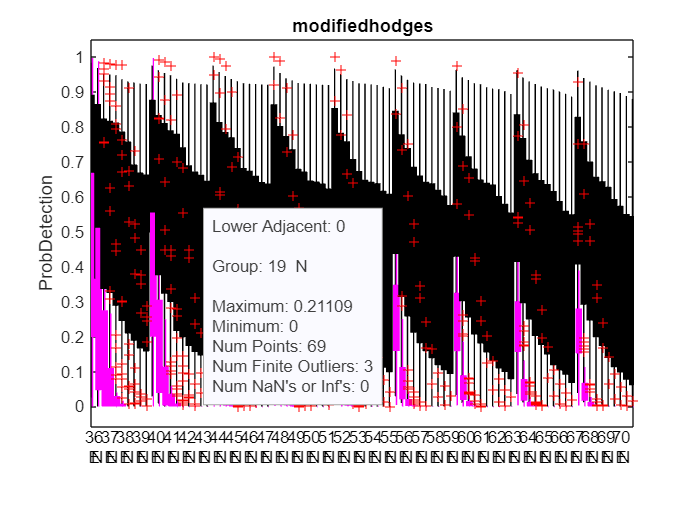

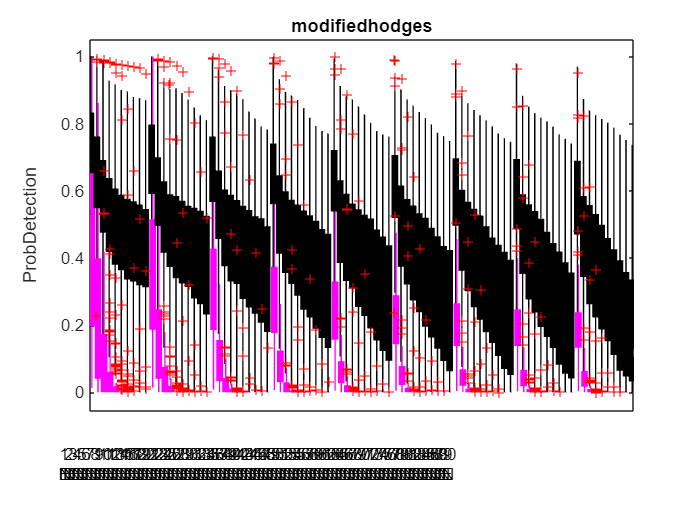

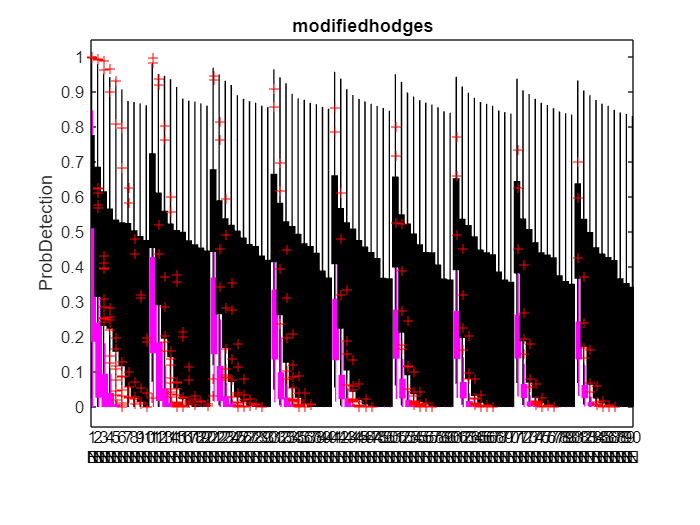

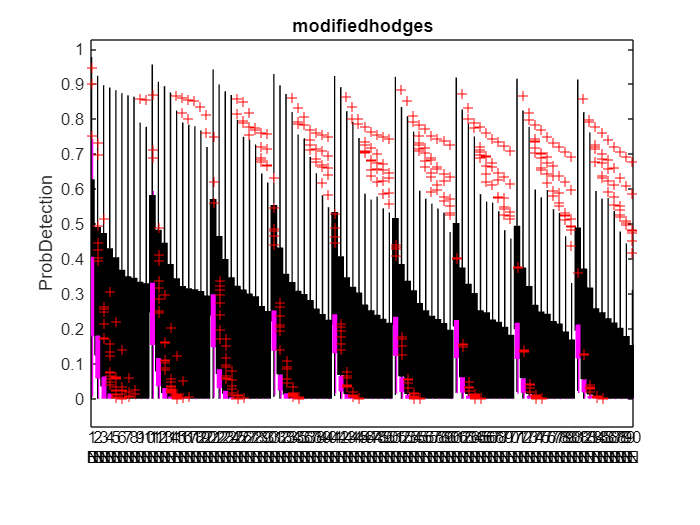

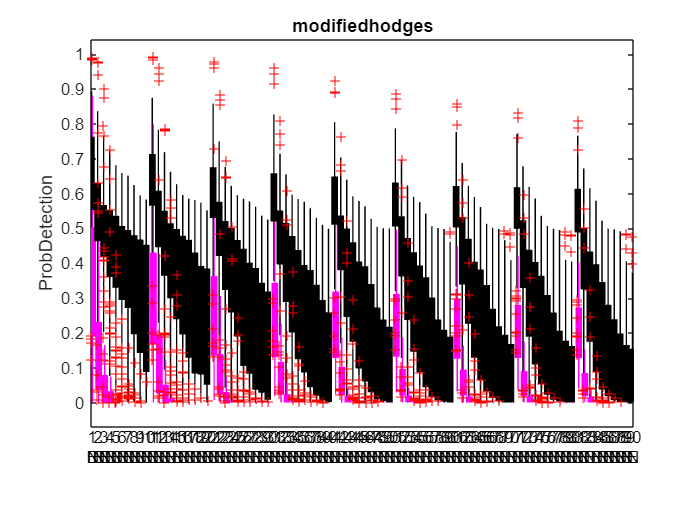

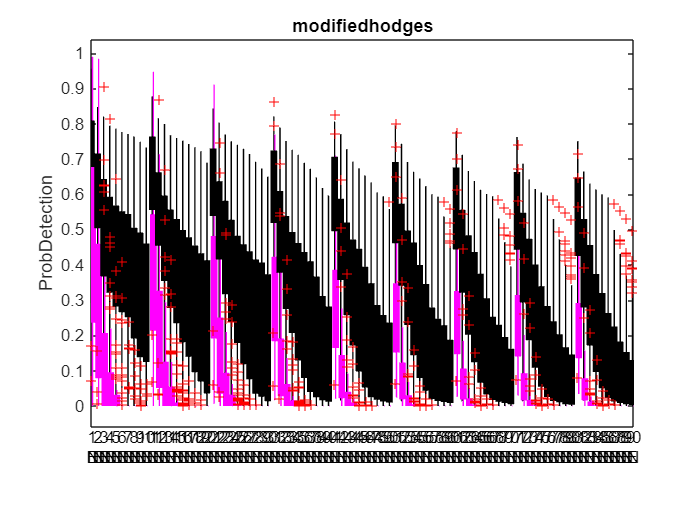

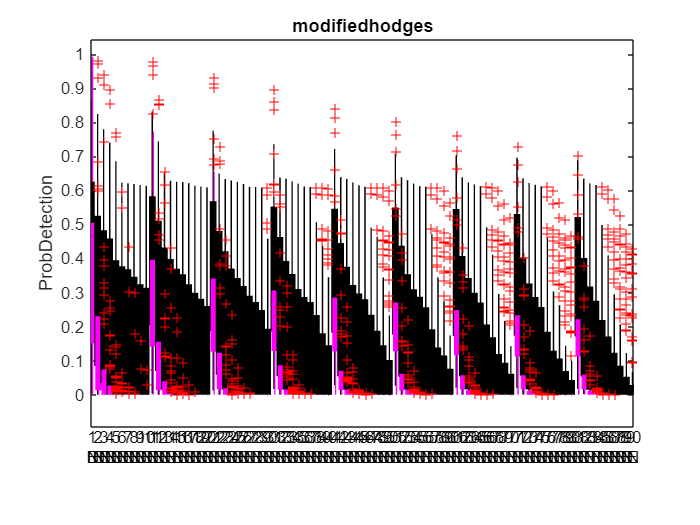

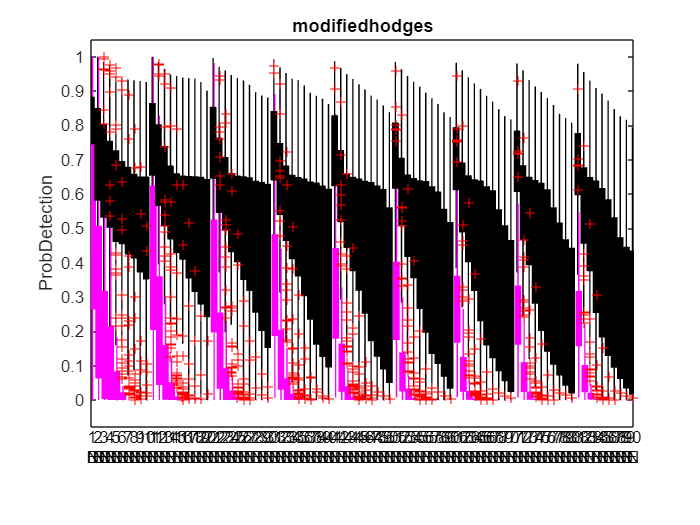

clc
clear all
close all

addpath 'E:\EMG_detectors\library'
Detectors = ["modifiedhodges"];
%%  Get the parameters
    mode = "Train";
    method = "";
    type = "";
    SNR = [];
   paramfuncname = strcat(Detectors(1), '_param');
   paramfunc =  str2func(paramfuncname);
   params = paramfunc(mode,type,SNR,Detectors(1),method);
   combo = 1:numel(params.combo);
   Params = string(combo);
    cutoff = params.fc;

NoTrialPatient = [30 69	95	77	89	90	77	90	95	25	90	61	85	61	55	14	62	90	85	71	53	75	95	80	73	2	27	82	55];

paramcombo = repmat(Params,1,2);
costfactors = [repmat({'E'},1,length(Params)),repmat({'N'},1,length(Params))];
MaxSepAllcombo = load('E:\EMG_detectors\detectors_review_paper\Probdetection\alphamodifiedhodgesPdALLcombo.mat');
for k = 2:length(NoTrialPatient)
    PmoveEMG = MaxSepAllcombo.H1(sum(NoTrialPatient(1:k-1))+1:sum(NoTrialPatient(1:k)),:); %MaxSepAllcombo.MaxSepAllcombo(:,1:2:end);
    PmoveNoise = MaxSepAllcombo.H0(sum(NoTrialPatient(1:k-1))+1:sum(NoTrialPatient(1:k)),:)  ;%MaxSepAllcombo.MaxSepAllcombo(:,2:2:end);
    % %% Plot boxplot of Pd
    figure(k)
    gcf.Position = [1 49 1536 836.8000];
    BoxplotData = [PmoveEMG PmoveNoise];
    boxplot(BoxplotData,{paramcombo,costfactors},'colors',repmat('km',1,2),'factorgap',[7 1],'labelverbosity','minor','BoxStyle','filled');
    ylabel('ProbDetection')
    title(Detectors(1))  
end